# Image Compression using SVD

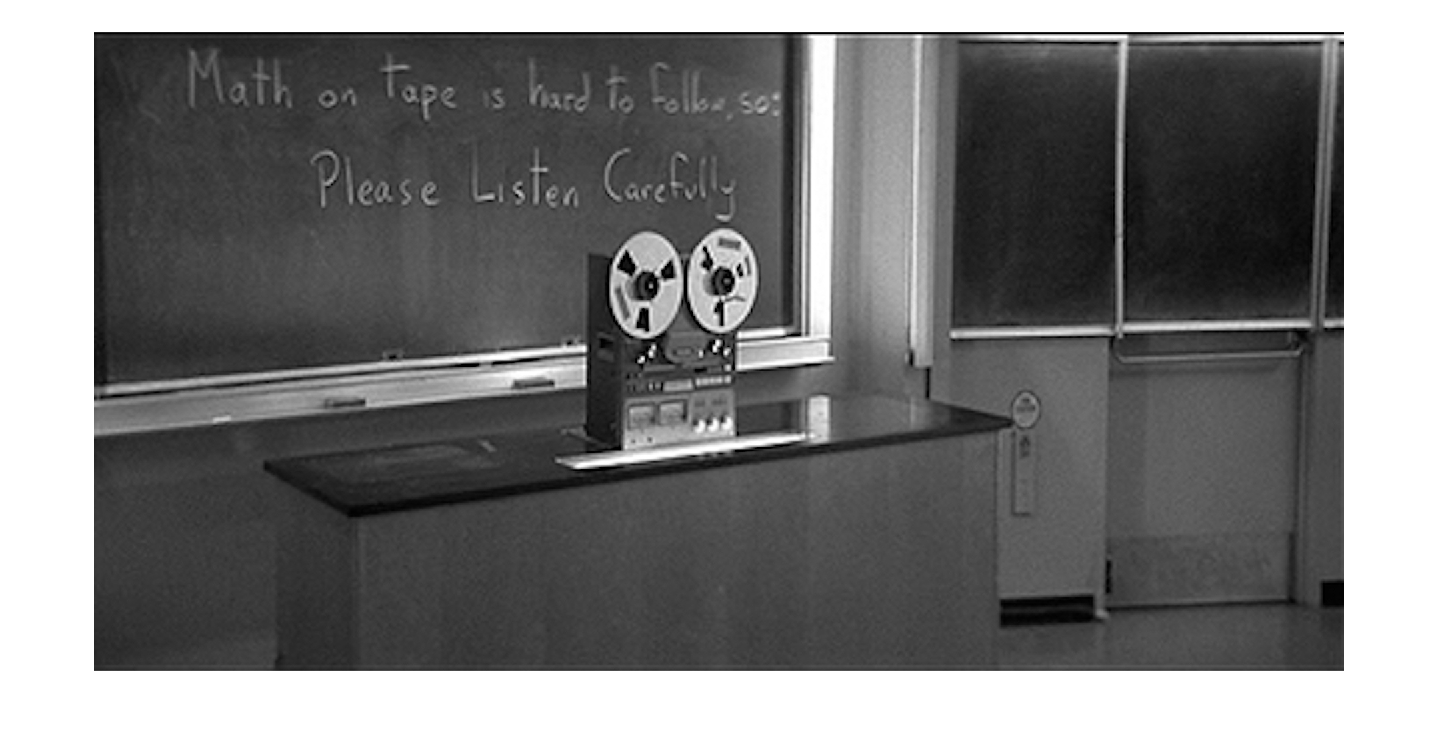

clear;clc;

img = double(rgb2gray(imread('../images/recorder.jpg')));
figure(1);
imshow(uint8(img));

## Image Compression

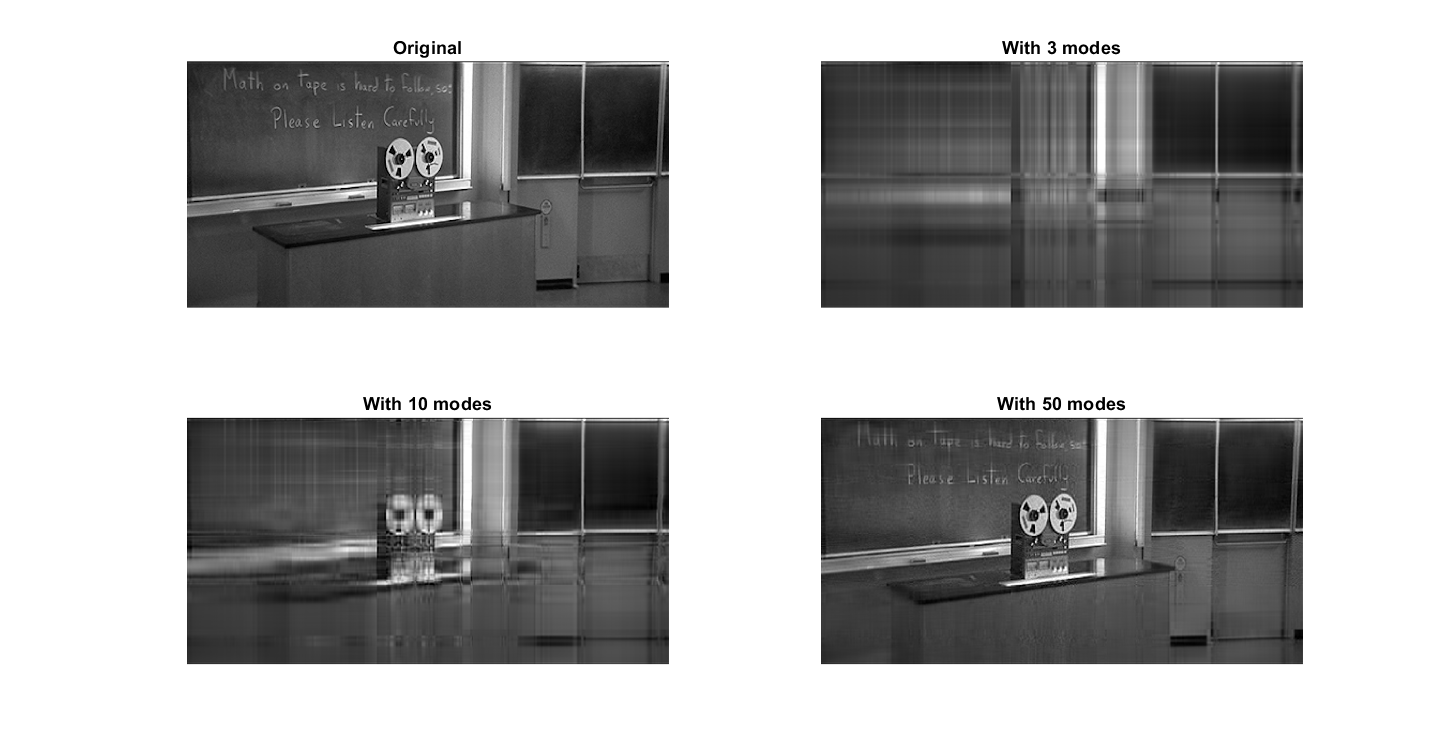

[U,S,V] = svd(img);
figure(1);
subplot(2,2,1);
imshow(uint8(img));
title('Original');
count = 2;
for k = [3 10 50]
    img_approx = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    subplot(2,2,count);
    imshow(uint8(img_approx));
    title(['With ' int2str(k) ' modes']);
    count = count + 1;
end

## Plot SVD Sigmas

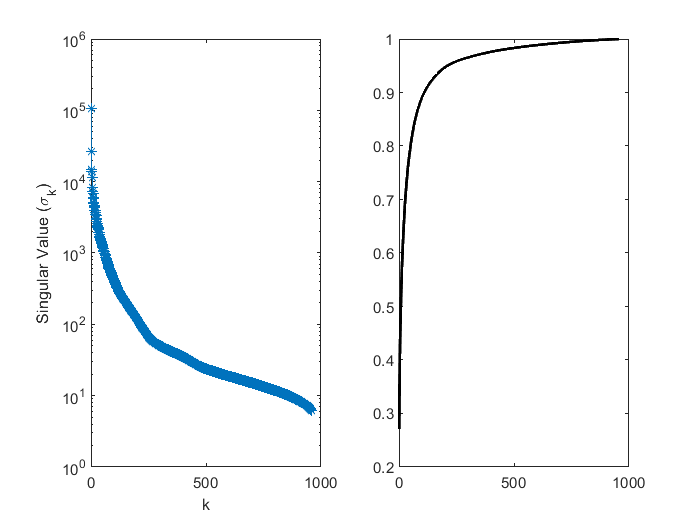

figure(3);
subplot(1,2,1);
semilogy(diag(S),'-*');
xlabel('k');
ylabel('Singular Value (\sigma_k)');
subplot(1,2,2);
plot(cumsum(diag(S))/sum(diag(S)), 'k', 'LineWidth', 1.5);